clc
clearvars
close all

% Define state space matrices
statename = {'q','\alpha','V','\gamma'};
A_LAT = [
    -0.9981, -2.5072, -3.518e-4, 0;
    0.9709, -0.9632, -0.0025, 0.0099;
    -0.1274, 4.6526, -0.0219, -9.7234;
    1, 0, 0, 0
];
inputname = {'\delta_t','\delta_e'};
B_LAT = [
    0.1335, -5.6897;
    -0.0048, -0.1038;
    2.9885, -0.6188;
    0, 0.0518
];
outputname = {'q','\alpha','V','\gamma'};
C_LAT = eye(4);
D_LAT = zeros(4,2);

## Task 1 - General SAS Design

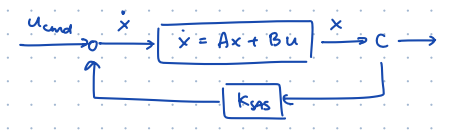

## Task 2 - Controller Design I

short period approximation with q and alpha with delta_e

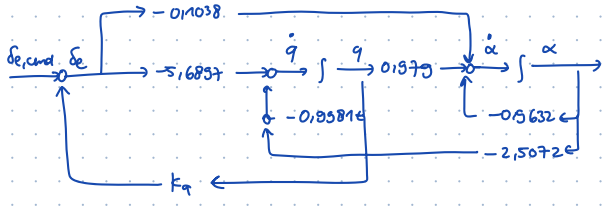

A_SP = A_LAT(1:2,1:2);
B_SP = B_LAT(1:2,2);
C_SP = eye(2);
D_SP = zeros(2,1);

sys_SP = ss(A_SP,B_SP,C_SP,D_SP,'StateName',statename(1:2),'OutputName',outputname(1:2),'InputName',inputname(2));
TF_SP = tf(sys_SP(1,1))


TF_SP =
 
  From input "\delta_e" to output "q":
     -5.69 s - 5.22
  ---------------------
  s^2 + 1.961 s + 3.396
 
Continuous-time transfer function.
Model Properties


% after calculation with hand of k_q
% [k_q^2 k_q 1]
k_q = roots([(5.69)^2, (4*0.49*5.22 - 2*1.961*5.69), ((1.961)^2-4*0.49*3.396)])

k_q =     0.5354
   -0.1621


% check which k_q makes sense
for i = 1:length(k_q)
    D = (1.961-5.69*k_q(i))/(2*sqrt(3.396-5.22*k_q(i)))
end

D = -0.7000

D = 0.7000

the first k_q resulted in negative damping, so we take the second k_q

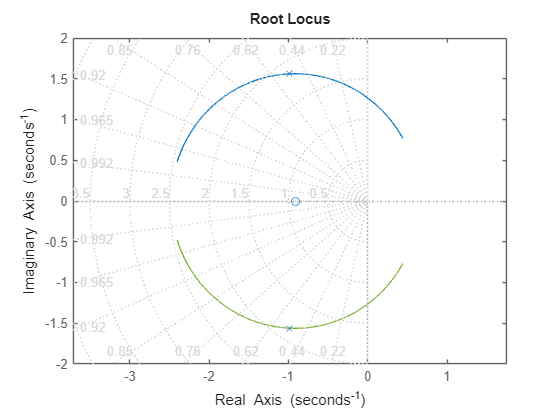

% check with plot
s = tf('s');
F_q_delta_e = tf([-5.69 -5.22],[1 1.961 3.396]);
figure()
rlocus(TF_SP,(-0.5:0.0001:0.5))
grid on
axis equal

## Task 3 - Controller Design II

full state feedback for short period mode

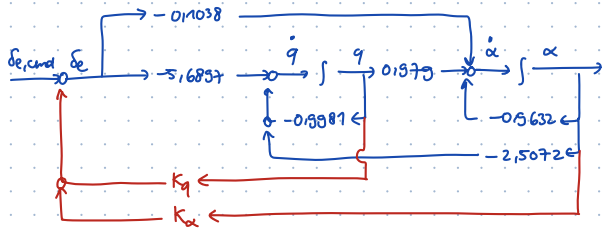

% Perform full state feeback so that the damping ratio is 0.7 and the
% undamped natural frequency is 0.4775 Hz -> (convert to rad/s)

% Steps
% 1. Check for possibility for pole placement with controllability matrix
% Q_c
Q_c = [
    B_SP, A_SP*B_SP
]

Q_c =    -5.6897    5.9391
   -0.1038   -5.4241


rank(Q_c)

ans = 2

% 2. Get T from last row of inverse of Q_c
Q_c_inv = inv(Q_c)

Q_c_inv =    -0.1723   -0.1887
    0.0033   -0.1808


T_inv = [
    Q_c_inv(end,:);...
    Q_c_inv(end,:)*A_SP
]

T_inv =     0.0033   -0.1808
   -0.1788    0.1658


T = inv(T_inv)

T =    -5.2201   -5.6897
   -5.6277   -0.1038


% 3. Rewrite in CCT form : build A_T
A_T = T_inv*A_SP*T

A_T =          0    1.0000
   -3.3956   -1.9613


% 4. Get desired poles, in this case D = 0.7 and natural freq. = 0.4775 Hz
omega_n = 2*pi*0.4775;
D = 0.7;

% coefficient of the char. polynom is the last row of A_T with added minus
% in front
char_coef = -A_T(end,:)

char_coef =     3.3956    1.9613


% with the eigenvalues of A_T
roots([1,char_coef(1),char_coef(2)])

ans =    -2.6576
   -0.7380


% our desired pole location (eigenvalues) on the root locus with sigma on real axis and
% omega on imaginary axis
sigma = -D*omega_n;
omega = omega_n*sqrt(1-D^2);

poles = [
    sigma+omega*1i, sigma-omega*1i
];

% we now compared the coefficient of char. polynomial between eigenvalues of A_T and
% eigenvalues of desired poles
a = char_coef

a =     3.3956    1.9613


% for a_d we need to flip because our char_coef from A_T is ordered from smallest to
% largest exponent
a_d = flip(poly(poles))

a_d =     9.0013    4.2003    1.0000


% now we just find the gain from the difference between desired poles and
% A_T poles
k_T = (a_d(1:2) - a)

k_T =     5.6057    2.2390


% 5. Transform back the gain to normal form
k = k_T*T_inv

k =    -0.3818   -0.6419


% 6. Simulate to check
A_SP_MOD = A_SP-B_SP*k

A_SP_MOD =    -3.1705   -6.1596
    0.9313   -1.0298


damp(A_SP_MOD)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -2.10e+00 + 2.14e+00i     7.00e-01       3.00e+00          4.76e-01    
 -2.10e+00 - 2.14e+00i     7.00e-01       3.00e+00          4.76e-01    


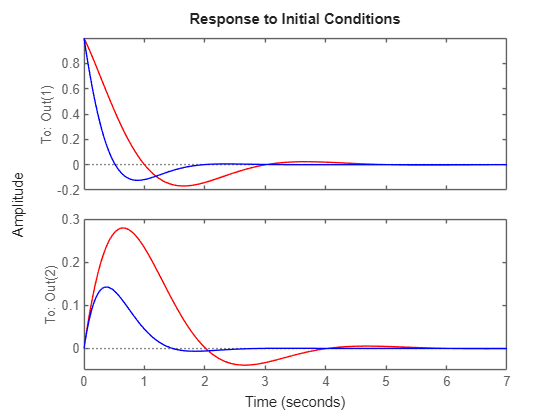

% plot
figure()
initial(ss(A_SP,B_SP,C_SP,D_SP),'r',[1,0])
hold on
initial(ss(A_SP_MOD,B_SP,C_SP,D_SP),'b',[1,0])

## Task 4 - Controller Design III

gain for phugoid mode by feeding back V to delta_t to achieve damping of 0.707

A_LAT_NEW = [
    A_SP_MOD(1,1), A_SP_MOD(1,2), A_LAT(1,3:4);
    A_SP_MOD(2,1), A_SP_MOD(2,2), A_LAT(2,3:4);
    A_LAT(3:4,:)
]

A_LAT_NEW =    -3.1705   -6.1596   -0.0004         0
    0.9313   -1.0298   -0.0025    0.0099
   -0.1274    4.6526   -0.0219   -9.7234
    1.0000         0         0         0


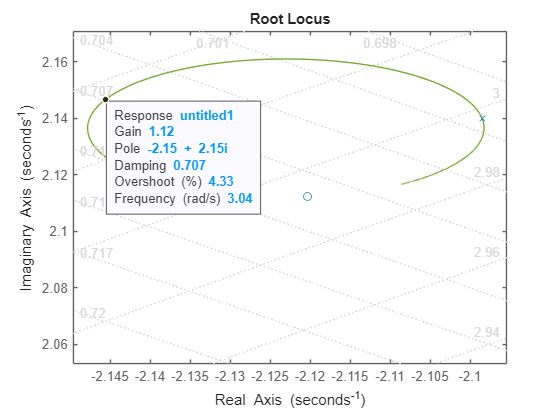

sys_LAT_MOD = ss(A_LAT_NEW,B_LAT,C_LAT,D_LAT,'StateName',statename,'OutputName',outputname,'InputName',inputname);

% determine gain manually from root locus to have a damping of 0.707 with
% V as output and delta_e as input
figure()
rlocus(sys_LAT_MOD(3,1),(-2:0.001:2))
grid on
axis equal

here we can see with gain of 1.12, damping ratio of 0.707 is achieved